%% AE 6355 - Individual Project - Major Upgrade #6: Bank-Angle Guidance
% Closed-loop bank-angle modulation guidance for the lifting Stage-7
% baseline (gamma_e=8.21 deg, L/D=0.3, constant beta=61 kg/m^2, planar).
% Since the planar EOM has no crossrange, bank angle only scales the
% vertical lift component - this is 1-DOF altitude-vs-velocity tracking,
% not full 3D steering.
%
% Stage A: generate a reference h(V) profile from one open-loop fixed-
%          bank (sigma=45 deg) run - the Stage-7 baseline itself.
% Stage B: closed-loop bank-angle feedback, commanding the vertical-lift
%          fraction u_L=cos(sigma) rather than sigma directly (more
%          consistent effective gain, since cos(sigma) is what actually
%          appears in the dgamma/dt equation):
%              u_cmd = cos(sigma_nom) - Kh*(h - h_ref(V))
%              sigma_cmd = acos(clamp(u_cmd))
%          Held at sigma_nom until dynamic pressure exceeds q_engage -
%          bank angle has negligible aerodynamic authority before then
%          (more robust across dispersed cases than a fixed time gate,
%          since it directly checks the physical condition rather than
%          assuming a fixed coast-phase duration).
% Stage C: verify nominal tracking (undispersed guided run should hug
%          the reference).
% Stage D: verify dispersion rejection - guided vs. unguided RMS
%          tracking error under the same dispersions used in the Monte
%          Carlo analysis (density, gamma0, V0).

clear; clc; close all;

%% -----------------------------------------------------------------
%% BASELINE CASE (Stage-7 lifting baseline)
%% -----------------------------------------------------------------
Re  = 6378150;
g0  = 9.81;
rho0 = 1.225;
H   = 7200;

V0     = 12799;
gamma0 = deg2rad(8.21);
h0     = 120000;
beta_const = 61;
LD_const   = 0.3;
sigma_nom  = deg2rad(45);   % nominal (unguided) fixed bank angle

skip_altitude = h0 + 100;
tspan = [0 8000];
ode_settings = {'RelTol',1e-8, 'AbsTol',[1e-3 1e-10 1e-3], 'MaxStep',0.5};

%% -----------------------------------------------------------------
%% STAGE A: REFERENCE h(V) PROFILE
%% -----------------------------------------------------------------
params_ref.Re = Re;
params_ref.beta = @(V,h) beta_const;
params_ref.LD   = @(V,h) LD_const;
params_ref.sigma = @(t) sigma_nom;   % time-based (unguided) for the reference run itself
params_ref.g_fun = @(h) g0*(Re/(Re+max(h,0)))^2;
params_ref.rho_fun = @(h) rho0*exp(-max(h,0)/H);

x0 = [V0; gamma0; h0];
opts = odeset(ode_settings{:}, 'Events', @(t,x) ground_skip_event(t,x,skip_altitude));
[t_ref, x_ref, ~, ~, ~] = ode45(@(t,x) EOM_3DOF(t, x, params_ref), tspan, x0, opts);

V_ref_traj = x_ref(:,1);
h_ref_traj = x_ref(:,3);

% V is NOT monotonic over the whole trajectory: in the near-vacuum coast
% phase before drag takes over, gravity briefly ACCELERATES the vehicle
% (confirmed via testing: V rises from 12799 to ~12808 m/s before turning
% over), so the same V value legitimately occurs at two very different
% altitudes near entry interface. Only use the trajectory from V's peak
% onward, where it becomes genuinely, monotonically decreasing. Also
% exclude the terminal-velocity plateau at the low-V end (V nearly
% constant while h drops sharply, confirmed via testing).
[V_peak, idx_peak] = max(V_ref_traj);
V_cutoff_ref = 200;   % m/s, excludes the terminal-velocity plateau
valid_ref = false(size(V_ref_traj));
valid_ref(idx_peak:end) = V_ref_traj(idx_peak:end) >= V_cutoff_ref;

[V_sorted, sort_idx] = sort(V_ref_traj(valid_ref));
h_sorted = h_ref_traj(valid_ref);
h_sorted = h_sorted(sort_idx);
[V_unique, unique_idx] = unique(V_sorted);
h_unique = h_sorted(unique_idx);
h_ref_interp = @(V) interp1(V_unique, h_unique, min(max(V,V_cutoff_ref), V_unique(end)), 'linear', 'extrap');

fprintf('Reference trajectory generated: %d points, V range [%.1f, %.1f] m/s\n', ...
    numel(V_ref_traj), min(V_ref_traj), max(V_ref_traj));

Reference trajectory generated: 6769 points, V range [31.0, 12807.9] m/s



%% -----------------------------------------------------------------
%% STAGE B/C: CLOSED-LOOP GUIDANCE, NOMINAL TRACKING CHECK
%% -----------------------------------------------------------------
Kh = 2.0e-4;                % change in lift fraction per meter of altitude error
% q_engage must clear the dynamic pressure AT the coast-phase V-peak
% (confirmed via testing: q_dyn=76 Pa at the nominal case's V-peak,
% t=10.6s) with margin for dispersed cases - a too-low threshold
% (originally 50 Pa) engages guidance BEFORE the peak, re-triggering the
% same V-ambiguity bug the reference interpolant was built to avoid.
q_engage = 150;             % Pa, dynamic pressure below which guidance holds at sigma_nom
sigma_min = 0; sigma_max = deg2rad(90);

params_guided = params_ref;
params_guided.sigma = @(V,h,rho) guidance_law(V, h, rho, h_ref_interp, sigma_nom, Kh, q_engage, sigma_min, sigma_max);

[t_g, x_g, ~, ~, ~] = ode45(@(t,x) EOM_3DOF_guided(t, x, params_guided), tspan, x0, opts);

h_ref_at_g = h_ref_interp(x_g(:,1));
% Exclude points before THIS trajectory's own V-peak (same ambiguity as
% the reference: V rises briefly before falling, so comparing against
% h_ref_interp - built only from post-peak data - is meaningless before
% the peak, confirmed via testing) AND below the terminal-velocity
% plateau (V<V_cutoff_ref).
active_mask = active_window(x_g(:,1), V_cutoff_ref);
tracking_err_nominal = x_g(:,3) - h_ref_at_g;
rms_err_nominal = sqrt(mean(tracking_err_nominal(active_mask).^2));
fprintf('Nominal (undispersed) guided run RMS tracking error: %.2f m\n', rms_err_nominal);

Nominal (undispersed) guided run RMS tracking error: 0.65 m


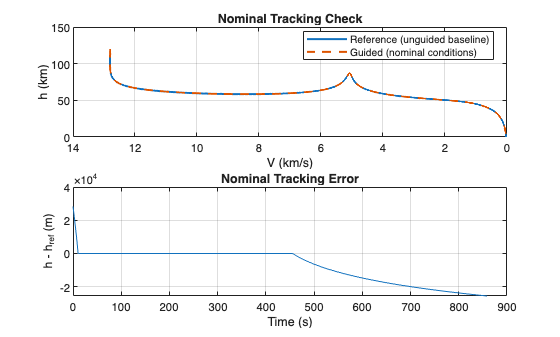


figure;
subplot(2,1,1);
plot(V_ref_traj/1000, h_ref_traj/1000, 'LineWidth',1.5); hold on;
plot(x_g(:,1)/1000, x_g(:,3)/1000, '--', 'LineWidth',1.5);
set(gca,'XDir','reverse'); xlabel('V (km/s)'); ylabel('h (km)');
legend('Reference (unguided baseline)', 'Guided (nominal conditions)', 'Location','best');
title('Nominal Tracking Check'); grid on;
subplot(2,1,2);
plot(t_g, tracking_err_nominal); xlabel('Time (s)'); ylabel('h - h_{ref} (m)');
title('Nominal Tracking Error'); grid on;


%% -----------------------------------------------------------------
%% STAGE D: DISPERSION REJECTION (guided vs. unguided)
%% -----------------------------------------------------------------
n_trials = 200;
sigma_rho_frac = 0.10;
sigma_gamma    = deg2rad(0.2);
sigma_V        = 10;
randn_clipped = @(sigma) max(min(sigma*randn(), 3*sigma), -3*sigma);

rms_err_guided   = nan(n_trials,1);
rms_err_unguided = nan(n_trials,1);

fprintf('Running %d dispersed trials (guided vs. unguided)...\n', n_trials);

Running 200 dispersed trials (guided vs. unguided)...


for i = 1:n_trials
    delta_rho = randn_clipped(sigma_rho_frac);
    gamma0_i  = gamma0 + randn_clipped(sigma_gamma);
    V0_i      = V0 + randn_clipped(sigma_V);
    x0_i = [V0_i; gamma0_i; h0];

    params_i = params_ref;
    params_i.rho_fun = @(h) rho0*(1+delta_rho)*exp(-max(h,0)/H);

    % Unguided: fixed sigma_nom
    [t_u, x_u] = ode45(@(t,x) EOM_3DOF(t, x, params_i), tspan, x0_i, opts);
    href_u = h_ref_interp(x_u(:,1));
    active_u = active_window(x_u(:,1), V_cutoff_ref);
    rms_err_unguided(i) = sqrt(mean((x_u(active_u,3)-href_u(active_u)).^2));

    % Guided: closed-loop sigma
    params_i_guided = params_i;
    params_i_guided.sigma = @(V,h,rho) guidance_law(V, h, rho, h_ref_interp, sigma_nom, Kh, q_engage, sigma_min, sigma_max);
    [t_gd, x_gd] = ode45(@(t,x) EOM_3DOF_guided(t, x, params_i_guided), tspan, x0_i, opts);
    href_gd = h_ref_interp(x_gd(:,1));
    active_gd = active_window(x_gd(:,1), V_cutoff_ref);
    rms_err_guided(i) = sqrt(mean((x_gd(active_gd,3)-href_gd(active_gd)).^2));

    if mod(i,50)==0
        fprintf('  %d/%d trials complete\n', i, n_trials);
    end
end

  50/200 trials complete
  100/200 trials complete
  150/200 trials complete
  200/200 trials complete



fprintf('\n--- DISPERSION REJECTION SUMMARY (%d trials) ---\n', n_trials);


--- DISPERSION REJECTION SUMMARY (200 trials) ---


fprintf('Unguided: mean RMS tracking error = %.2f m, std = %.2f m\n', ...
    mean(rms_err_unguided), std(rms_err_unguided));

Unguided: mean RMS tracking error = 5538.38 m, std = 3004.46 m


fprintf('Guided:   mean RMS tracking error = %.2f m, std = %.2f m\n', ...
    mean(rms_err_guided), std(rms_err_guided));

Guided:   mean RMS tracking error = 3169.83 m, std = 2476.81 m


fprintf('Improvement: %.1f%% reduction in mean RMS tracking error\n', ...
    100*(mean(rms_err_unguided)-mean(rms_err_guided))/mean(rms_err_unguided));

Improvement: 42.8% reduction in mean RMS tracking error


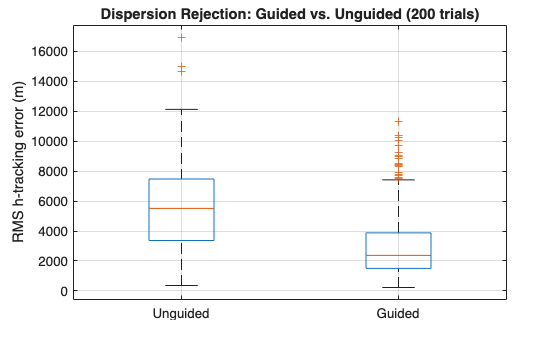


figure;
boxplot([rms_err_unguided, rms_err_guided], 'Labels', {'Unguided','Guided'});
ylabel('RMS h-tracking error (m)');
title(sprintf('Dispersion Rejection: Guided vs. Unguided (%d trials)', n_trials));
grid on;


%% ===================================================================
%% LOCAL FUNCTIONS
%% ===================================================================

function mask = active_window(V_traj, V_cutoff_ref)
% True for points at or after this trajectory's own V-peak AND above the
% terminal-velocity plateau. Both regions make h_ref_interp comparisons
% meaningless: pre-peak V is ambiguous (same V occurs at two very
% different altitudes, confirmed via testing), and the terminal-velocity
% plateau has trajectories independently traversing very different
% altitudes at nearly the same low V.
    [~, idx_peak] = max(V_traj);
    mask = false(size(V_traj));
    mask(idx_peak:end) = V_traj(idx_peak:end) >= V_cutoff_ref;
end

function sigma_cmd = guidance_law(V, h, rho, h_ref_interp, sigma_nom, Kh, q_engage, sigma_min, sigma_max)
% Commands the vertical-lift fraction u_L=cos(sigma) linearly (more
% consistent effective gain than commanding sigma directly, since
% cos(sigma) is what actually appears in the dgamma/dt equation). Held
% at sigma_nom until dynamic pressure clears q_engage - bank angle has
% negligible aerodynamic authority before then.
    q_dyn = 0.5*rho*V^2;
    if q_dyn < q_engage
        sigma_cmd = sigma_nom;
        return;
    end
    h_ref = h_ref_interp(V);
    err = h - h_ref;   % positive error = higher than reference -> need more drag/less lift support -> increase bank
    u_cmd = cos(sigma_nom) - Kh*err;
    u_min = cos(sigma_max); u_max = cos(sigma_min);
    u_cmd = min(max(u_cmd, u_min), u_max);
    sigma_cmd = acos(u_cmd);
end

function [value, isterminal, direction] = ground_skip_event(t, x, skip_altitude)
    h = x(3);
    value      = [h; h - skip_altitude];
    isterminal = [1; 1];
    direction  = [-1; +1];
end

function xdot = EOM_3DOF(t, x, params)
% Standard planar EOM, sigma is a function of t (unguided/reference use).
    V     = x(1);
    gamma = x(2);
    h     = x(3);

    if V <= 0
        error('Nonpositive velocity at t=%.6f s.', t);
    end

    h_env = max(h, 0);
    Re    = params.Re;
    beta  = params.beta(V, h_env);
    LD    = params.LD(V, h_env);
    sigma = params.sigma(t);
    g     = params.g_fun(h_env);
    rho   = params.rho_fun(h_env);

    dVdt     = -rho*V^2/(2*beta) + g*sin(gamma);
    dgammadt = -V*cos(gamma)/(Re + h) - (rho*V/(2*beta))*LD*cos(sigma) + g*cos(gamma)/V;
    dhdt     = -V*sin(gamma);

    xdot = [dVdt; dgammadt; dhdt];
end

function xdot = EOM_3DOF_guided(t, x, params)
% Planar EOM with closed-loop bank angle: sigma is a function of
% (V,h,rho) (state/dynamic-pressure feedback) instead of (t).
    V     = x(1);
    gamma = x(2);
    h     = x(3);

    if V <= 0
        error('Nonpositive velocity at t=%.6f s.', t);
    end

    h_env = max(h, 0);
    Re    = params.Re;
    beta  = params.beta(V, h_env);
    LD    = params.LD(V, h_env);
    g     = params.g_fun(h_env);
    rho   = params.rho_fun(h_env);
    sigma = params.sigma(V, h_env, rho);   % state/q_dyn feedback, not time-based

    dVdt     = -rho*V^2/(2*beta) + g*sin(gamma);
    dgammadt = -V*cos(gamma)/(Re + h) - (rho*V/(2*beta))*LD*cos(sigma) + g*cos(gamma)/V;
    dhdt     = -V*sin(gamma);

    xdot = [dVdt; dgammadt; dhdt];
end